# Guião 3

## Exercicio 1

% resolver em papel

## Exercicio 2 - Usar a função para os coefs da alinea 1

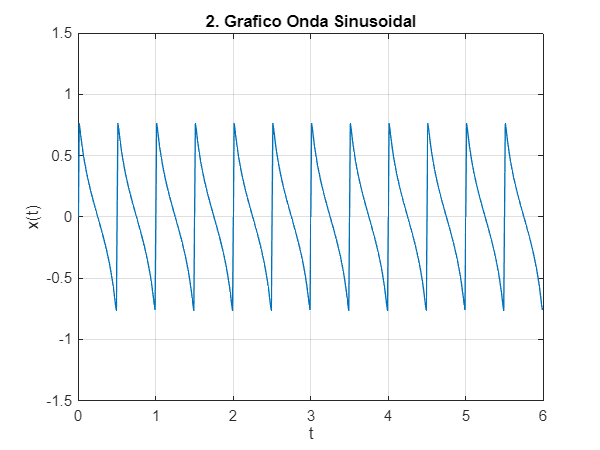

f0 = 1;
k = 100;
Ta = 0.01;
ak = zeros(1,k);
bk = zeros(1,k);
np = 6;

even = 1:2:k-1;                     % de 1 a k-1 de dois em dois (impares)
bk(even) = 4./(even*pi);            % expressão de bk quando k é impar

[x,t] = SomaFourier(Ta,f0,6,ak,bk);

figure
plot(t,x)
ylim([-1.5,1.5]);
xlabel('t');
ylabel('x(t)');
title("2. Grafico Onda Sinusoidal");
grid on;

## Exercicio 4 - Calculo de coefs da serie de Fourier de um sinal

clear all;
k = 100;                                % qtd de termos de ak e bk
Ta = 0.001;                             % período de amostragem

T = 1;                                  % período do sinal
f = 1/T;                                % frequencia

np = 4;                                 % tempo a considerar
t=0:Ta:T;                     

x = sawtooth(2*pi*f*t+pi/2, 1/2);      % função para obter a expressão do gráfico
                                        % x(t) = sawthoot(2*pi*f*t + fi)
                                        % 
                                        % 2arg : indica que o valor maximo
                                        % deve entre os dois zeros
                                        %   
 
[ak,bk] = CoefFourier(Ta,T,x,k);

[x,t] = SomaFourier(Ta,f,np,ak,bk);
x

x =    -0.0040    0.0000    0.0040    0.0080    0.0120    0.0160    0.0200    0.0240    0.0280    0.0320    0.0360    0.0400    0.0440    0.0480    0.0520    0.0560    0.0600    0.0640    0.0680    0.0720    0.0760    0.0800    0.0840    0.0880    0.0920    0.0960    0.1000    0.1040    0.1080    0.1120    0.1160    0.1200    0.1240    0.1280    0.1320    0.1360    0.1400    0.1440    0.1480    0.1520    0.1560    0.1600    0.1640    0.1680    0.1720    0.1760    0.1800    0.1840    0.1880    0.1920


t

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


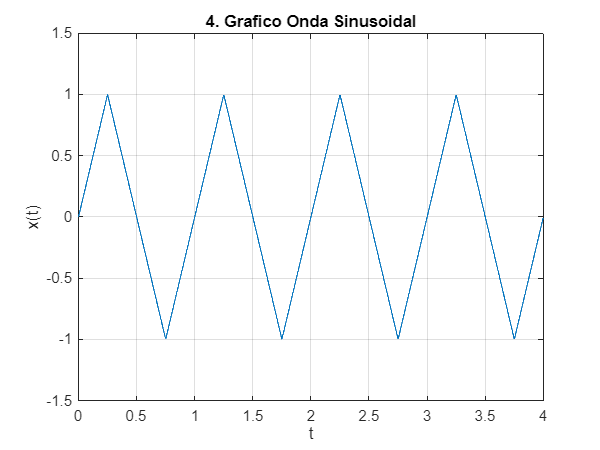



figure;
plot(t,x);
ylim([-1.5,1.5]);
xlabel('t');
ylabel('x(t)');
title("4. Grafico Onda Sinusoidal");
grid on;

## Funções

function[x,t] = SomaFourier(Ta, f0, np, a, b)
    %
    %   Ta : Período de amostragem, em segundos;
    %   f0 : Frequência do sinal composto, em Hz;
    %   np : Número de períodos a considerar para o sinal resultante;
    %   a : Vetor (Kx1) com os valores de ak da série;
    %   b : Vetor (Kx1) com os valores de bk da série.
    %   
    %   x : sinal resultante da soma dos termos de fourier  
    %   t : vetor de tempo correspondente a cada amostra do sinal
    
    T0 = 1/f0;                      % periodo fundamental do sinal composto
    t = 0:Ta:np*T0-Ta;
    L = length(a);                  % número de termos da serie de fourier
    x = 0;

    for k = 1:L
        x = x + a(k)*cos(2*pi*(k-1)*f0*t) + b(k)*sin(2*pi*(k-1)*f0*t);
    end
end


function[ak, bk] = CoefFourier(Ta,T0,x,k)
    %   
    %   Ta : Periodo de amostragem
    %   T0 : Período do sinal
    %   x : vetor de amostras do sinal
    %   k : número de termos a considerar
    %
    %   vetor de coefs ak (para termos de cosseno)
    %   vetor de coefs bk (para termos de seno)
    
    ak = zeros(1, k);
    bk = zeros(1, k);
    
    N = T0/Ta;                                                  % numero de amostras
    f = 1/T0;                                                   % frequencia
    
    for n = 1:N                                                 % somatório para a0
        ak(1) = ak(1) + (1/N)*x(n); 
    end
    
    for k1 = 2:k
        for n=1:N
            ak(k1) = ak(k1) + 2/N * x(n) * cos(2*pi*(k1-1)*f*n*Ta); % como os indices começam em um e o somatorio começa em 0 temos de usar (k-1) dentro das trignométricas
            bk(k1) = bk(k1) + 2/N * x(n) * sin(2*pi*(k1-1)*f*n*Ta);
        end
    end
end